# Demo1: Predict Transformer Health

## Demo 1: Predict Transformer Health using Supervised Machine Learning

Power utilities operate large numbers of transformers across substations.

Monitoring the health of these assets is essential to maintain reliable power system operation.

**Utilities typically collect condition monitoring data such as:**

- Transformer age

- Load level

- Oil temperature

- Moisture content

- Dissolved gas analysis (DGA)

- Partial discharge

- Vibration

These variables provide valuable information about transformer condition.

In this demonstration, we use machine learning to predict the health status of transformers based on condition monitoring data.

The target variable is defined as:

HealthStatus

- Healthy

- Monitor

- Critical

## Step 1 — Load Dataset

In this step, we import a dataset containing simulated transformer monitoring data.

Each row represents the operating condition of a transformer.

data = readtable("Utilities_Transformer_Health_210pts.xlsx");
head(data)

    SubstationID    TransformerID    VoltageLevel_kV    TransformerAge_Years    LoadPercent    OilTemp_C    AmbientTemp_C    Moisture_ppm    H2_ppm    CO_ppm    PartialDischarge_pC    Vibration_mm_s    HealthStatus
    ____________    _____________    _______________    ____________________    ___________    _________    _____________    ____________    ______    ______    ___________________    ______________    ____________
     {'SS-03'}       {'TR-015'}            230                   31                 119           107            30             

## Step 2 — Explore Dataset

Before training a machine learning model, it is important to understand the dataset.

summary(data)

data: 210×13 table
Variables:
    SubstationID: cell array of character vectors
    TransformerID: cell array of character vectors
    VoltageLevel_kV: double
    TransformerAge_Years: double
    LoadPercent: double
    OilTemp_C: double
    AmbientTemp_C: double
    Moisture_ppm: double
    H2_ppm: double
    CO_ppm: double
    PartialDischarge_pC: double
    Vibration_mm_s: double
    HealthStatus: cell array of character vectors
Statistics for applicable variables:
                            NumMissing       Min           Median           Max            Mean            Std     
    SubstationID                0                     

## Step 3 — Check Label Distribution

Understanding the distribution of labels helps ensure the dataset is suitable for training classification models.

tabulate(data.HealthStatus)

     Value    Count   Percent
  Critical       70     33.33%
   Monitor       70     33.33%
   Healthy       70     33.33%


## Step 4 — Data Visualization

In this example, we visualize the relationship between oil temperature and vibration level. Using Live Task

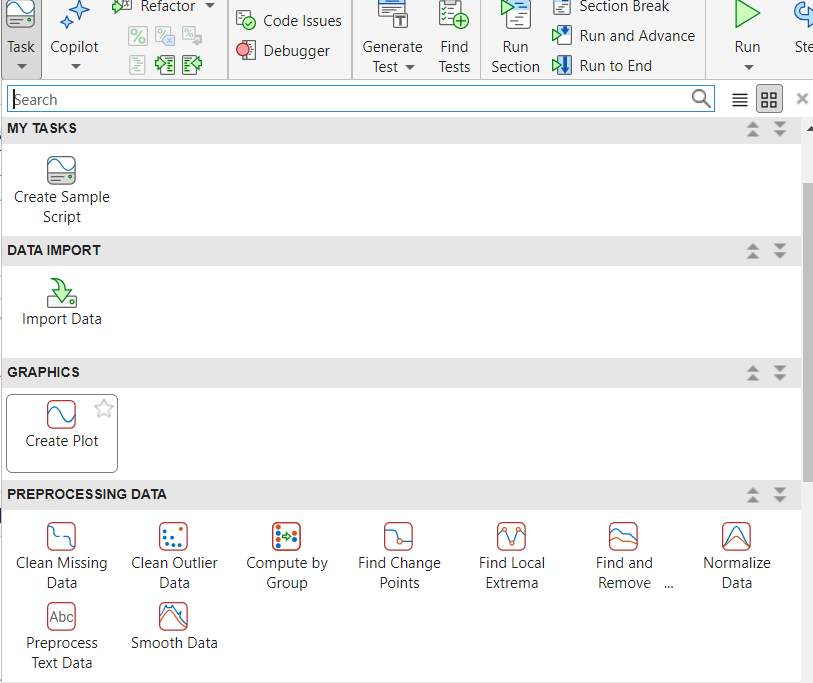

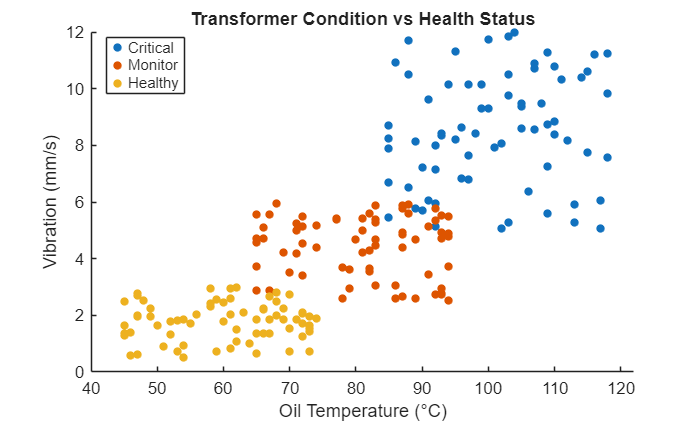

figure
gscatter(data.OilTemp_C, data.Vibration_mm_s, data.HealthStatus)
xlabel("Oil Temperature (°C)")
ylabel("Vibration (mm/s)")
title("Transformer Condition vs Health Status")

Using Live Task

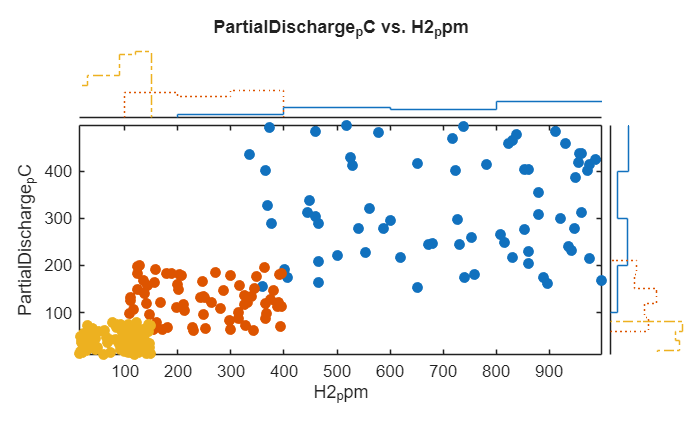

% Create scatterhistogram of selected data
sh = scatterhistogram(data.H2_ppm,data.PartialDischarge_pC,"GroupData",data.HealthStatus);

% Add xlabel, ylabel, and title
xlabel("H2_ppm")
ylabel("PartialDischarge_pC")
title("PartialDischarge_pC vs. H2_ppm")

## Step 5 — Train Machine Learning Model

In this step, we launch the Classification Learner app to train a supervised machine learning model.

Response variable: HealthStatus

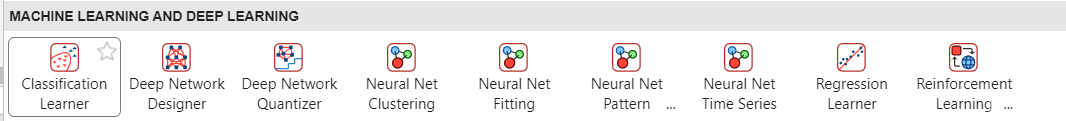

classificationLearner

## Step 6 — Model Evaluation

We evaluate models using validation accuracy and confusion matrices.

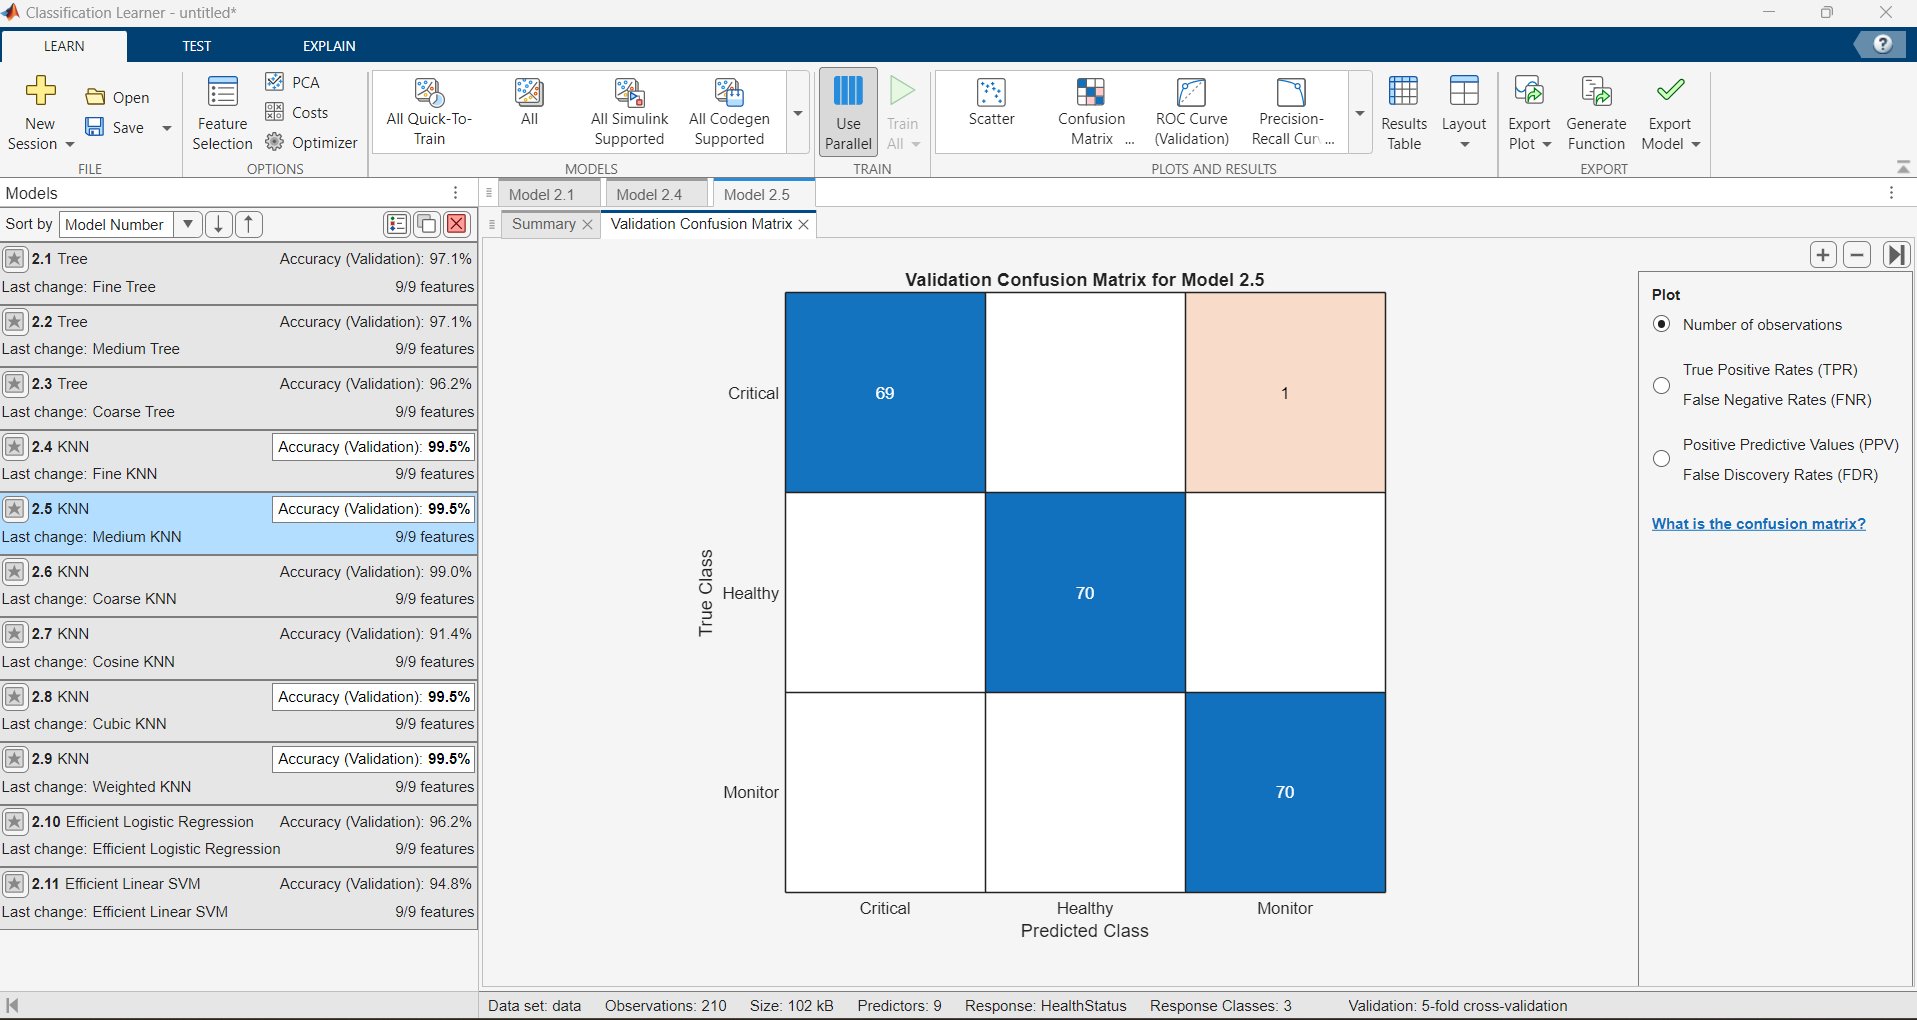

## Step 7 — Export Trained Model

After selecting the best performing model, we export the trained model to the MATLAB workspace.

This model can then be used for prediction or integrated into engineering applications.

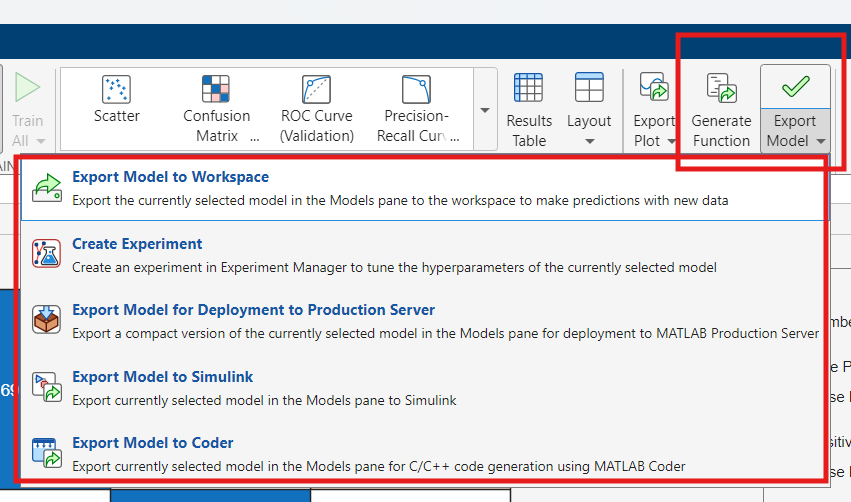

After select "Export Model to Workspace"

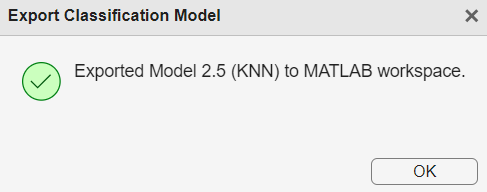

save modelSVM.mat trainedModel2

## Step 8 — Predict Transformer Health

Once the model is trained, it can be used to predict the health status of new transformer data.

sample = data(1:5,:);

sample.HealthStatus = [];

predictedStatus = trainedModel.predictFcn(sample)

predictedStatus = 5×1 cell array
    {'Critical'}
    {'Critical'}
    {'Monitor' }
    {'Critical'}
    {'Critical'}

## Summary Key Takeaway

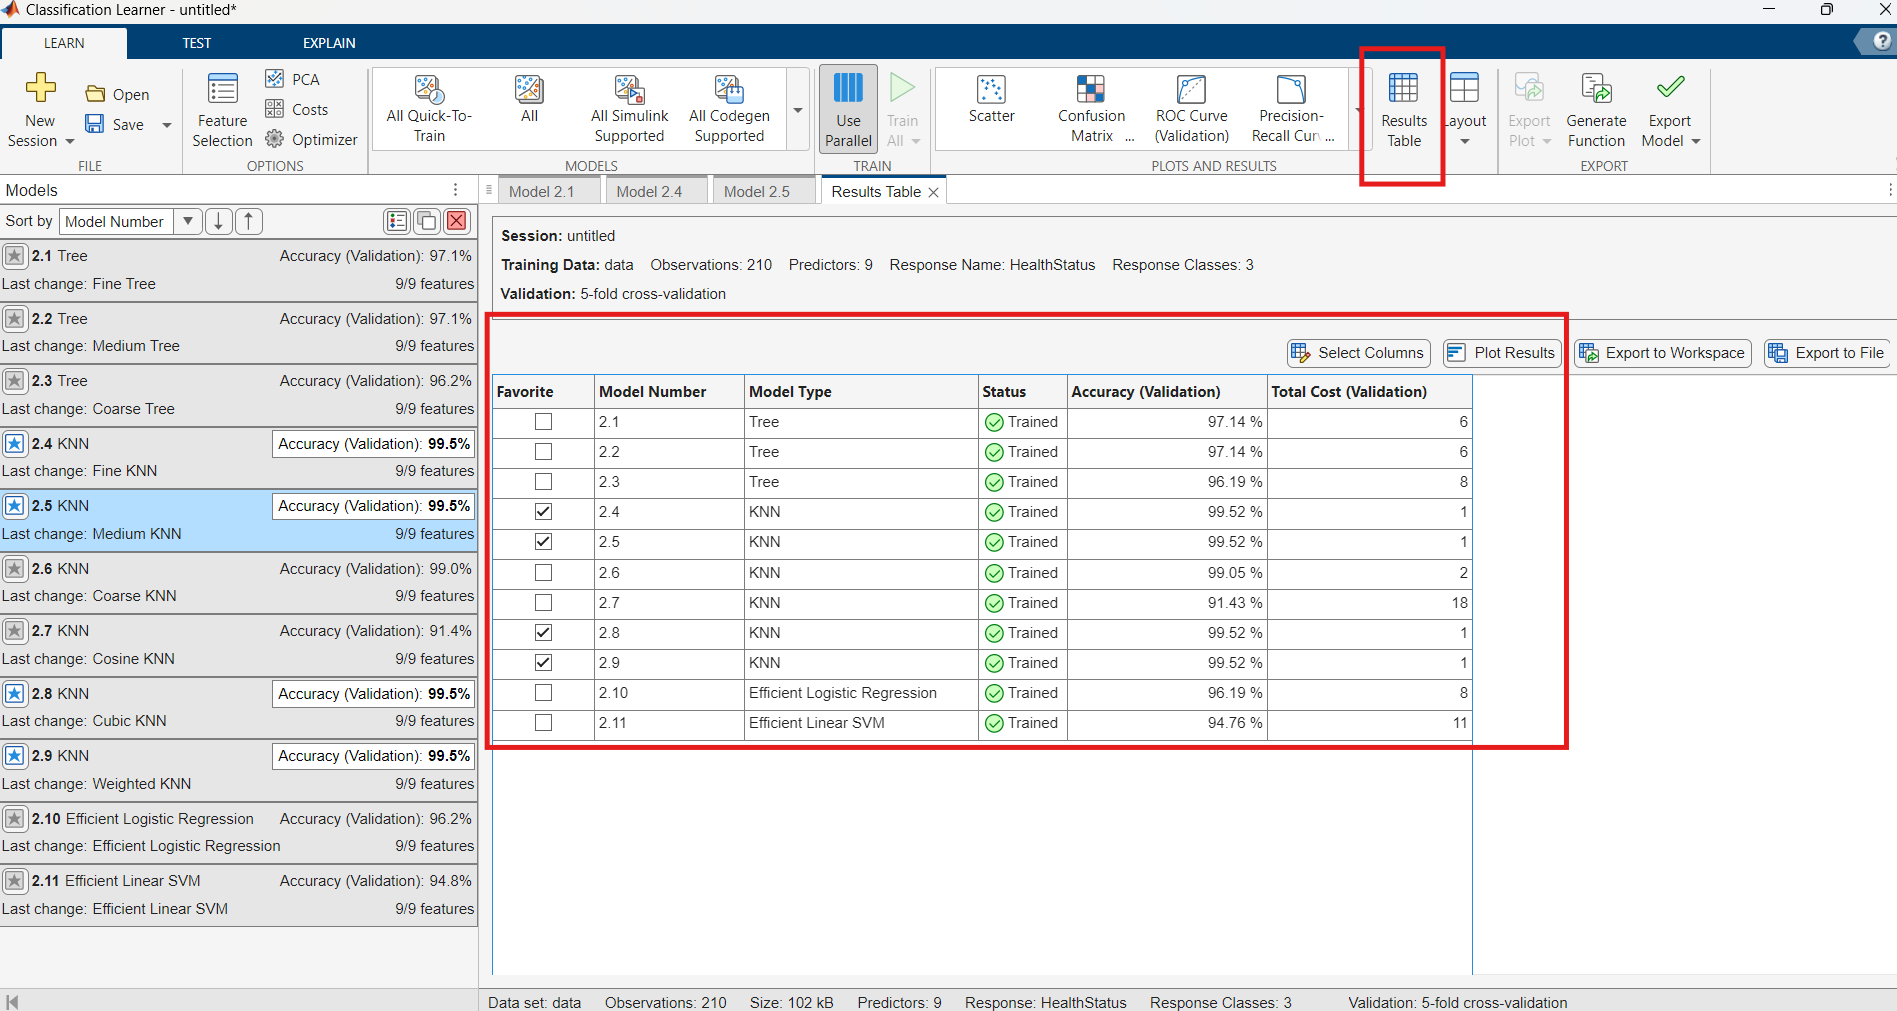

In this demonstration, we showed how supervised machine learning can be used to predict transformer health status.

**Key steps included:**

- Importing condition monitoring data

- Exploring and visualizing the dataset

- Training classification models

- Evaluating model performance

- Predicting transformer health status

This approach can support utilities in asset condition monitoring and maintenance planning.